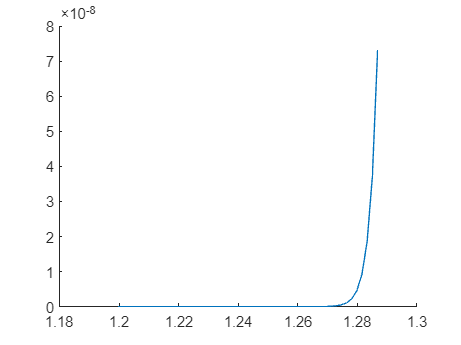

A =3;
n=sqrt(A);
L_0=12*10^-9;
L=linspace(2*10^-9, 15*10^-9, 500);
E_g=0.83;
E_gGaAs = 1.52;
m_0 = 9.1093837*10^(-31);
me_eff= 0.067;
mh_eff= 0.45;
mbe=0.041;
mbh=0.417;
% m_0 = 9.1093837*10^(-31);
hbar = 1.0545718*10^(-34);
mu = 1/(1/(m_0*mbe)+1/(m_0*mbh));
q=1.60217663*10^-19;
photon_energy=linspace (0.4, 2.4, 500);
x= photon_energy-E_g;
chi = sqrt((2*mu*L_0^2*x*q)/(pi^2*hbar^2));

xeta=0.02;
% 
% relative_absorption = (1/ (xeta * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta^2));
% 
% xeta_2=0.06;
% 
% relative_absorption_2 = (1/ (xeta_2 * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta_2^2));
% 
% xeta_3=0.1;
% 
% relative_absorption_3 = (1/ (xeta_3 * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta_3^2));
% 
% xeta_4=0.14;
% 
% relative_absorption_4 = (1/ (xeta_4 * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta_4^2));

EC=0.6;
EV=0.4;
Ve=(E_gGaAs-E_g)*(EC);
Vh=(E_gGaAs-E_g)*(EV);
%mbe=0.023;
%mbh=0.4;
P=(hbar^2)*me_eff*m_0;
R=(mbe*m_0)^2*(L_0)^2*(Ve)*q;
S=(hbar^2)*mh_eff*m_0;
T=(mbh*m_0)^2*(L_0^2)*(Vh)*q;
B=P/R;
C=S/T;
Ye=1-B;
Yh=1-C;
Mme=(mbe)/Ye;
Mmh=(mbh)/Yh;
mub = 1/(1/(Mme*m_0)+1/(Mmh*m_0));
Ee=(pi.^2.*hbar.^2.*A)./(2.*Mme.*m_0.*q.*L.^2);
Eh=(pi.^2.*hbar.^2.*A)./(2.*Mmh.*m_0.*q.*L.^2);

for c=1: length (Ee)
    if Ee(c)<=0
        Ee(c)=NaN;
    end
    if Ee(c)>=0 && Ee(c)<=Ve
        Ee(c)=Ee(c);
    end
    if Ee(c)>=Ve
    Ee(c)=NaN;
    end
    end
Ee;
for d=1: length (Eh)
    if Eh(d)<=0
        Eh(d)=NaN;
    end
    if Eh(d)>=0 && Eh(d)<=Vh
        Eh(d)=Eh(d);
    end
    if Eh(d)>=Vh
    Eh(d)=NaN;
    end
    end
Eh;

photon_energy2=E_g+Ee+Eh;
x2= photon_energy2-E_g;

chi3= sqrt((2 .* mub .* L_0.^2 .* x2.* q) ./ (pi.^2 .* hbar.^2));





relative_absorption_5 = (1/ (xeta * n.^2)) .* exp((-(n ./ chi3 - 1).^2) ./ (2 * xeta^2));


% 
% relative_absorption_6 = (1/ (xeta_2 * n.^2)) .* exp((-(n ./ chi3 - 1).^2) ./ (2 * xeta_2^2));
% 
% 
% 
% relative_absorption_7 = (1/ (xeta_3 * n.^2)) .* exp((-(n ./ chi3 - 1).^2) ./ (2 * xeta_3^2));
% 
% 
% 
% relative_absorption_8 = (1/ (xeta_4 * n.^2)) .* exp((-(n ./ chi3 - 1).^2) ./ (2 * xeta_4^2));



%plot(photon_energy,relative_absorption,'--')
hold on
%plot(photon_energy,relative_absorption_2,'--')
%plot(photon_energy,relative_absorption_3,'--')
%plot(photon_energy,relative_absorption_4,'--')
% plot(photon_energy2,relative_absorption_5)
% plot(photon_energy2,relative_absorption_6)
% plot(photon_energy2,relative_absorption_7)
% plot(photon_energy2,relative_absorption_8)

A=6;
n=sqrt(A);
L_0=9*10^-9;
L=linspace(2*10^-9, 15*10^-9, 500);
E_g=0.83;
E_gGaAs = 1.52;
m_0 = 9.1093837*10^(-31);
me_eff= 0.067;
mh_eff= 0.45;
mbe=0.041;
mbh=0.417;
m_0 = 9.1093837*10^(-31);
hbar = 1.0545718*10^(-34);
mu = 1/(1/(m_0*mbe)+1/(m_0*mbh));
q=1.60217663*10^-19;
photon_energy=linspace (0.4, 2.4, 500);
x= photon_energy-E_g;
chi = sqrt((2*mu*L_0^2*x*q)/(pi^2*hbar^2));

% xeta=0.02;
% 
% relative_absorption = (1/ (xeta * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta^2));
% 
% xeta_2=0.06;
% 
% relative_absorption_2 = (1/ (xeta_2 * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta_2^2));
% 
% xeta_3=0.1;
% 
% relative_absorption_3 = (1/ (xeta_3 * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta_3^2));
% 
% xeta_4=0.14;
% 
% relative_absorption_4 = (1/ (xeta_4 * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta_4^2));

EC=0.6;
EV=0.4;
Ve=(E_gGaAs-E_g)*(EC);
Vh=(E_gGaAs-E_g)*(EV);
%mbe=0.023;
%mbh=0.4;
P=(hbar^2)*me_eff*m_0;
R=(mbe*m_0)^2*(L_0)^2*(Ve)*q;
S=(hbar^2)*mh_eff*m_0;
T=(mbh*m_0)^2*(L_0^2)*(Vh)*q;
B=P/R;
C=S/T;
Ye=1-B;
Yh=1-C;
Mme=(mbe)/Ye;
Mmh=(mbh)/Yh;
mub = 1/(1/(Mme*m_0)+1/(Mmh*m_0));
Ee=(pi.^2.*hbar.^2.*A)./(2.*Mme.*m_0.*q.*L.^2);
Eh=(pi.^2.*hbar.^2.*A)./(2.*Mmh.*m_0.*q.*L.^2);

for c=1: length (Ee)
    if Ee(c)<=0
        Ee(c)=NaN;
    end
    if Ee(c)>=0 && Ee(c)<=Ve
        Ee(c)=Ee(c);
    end
    if Ee(c)>=Ve
    Ee(c)=NaN;
    end
    end
Ee;
for d=1: length (Eh)
    if Eh(d)<=0
        Eh(d)=NaN;
    end
    if Eh(d)>=0 && Eh(d)<=Vh
        Eh(d)=Eh(d);
    end
    if Eh(d)>=Vh
    Eh(d)=NaN;
    end
    end
Eh;

photon_energy2=E_g+Ee+Eh;
x2= photon_energy2-E_g;

chi3= sqrt((2 .* mub .* L_0.^2 .* x2.* q) ./ (pi.^2 .* hbar.^2));





relative_absorption_9 = (1/ (xeta * n.^2)) .* exp((-(n ./ chi3 - 1).^2) ./ (2 * xeta^2));


A=9;
n=sqrt(A);
L_0=9*10^-9;
L=linspace(2*10^-9, 15*10^-9, 500);
E_g=0.83;
E_gGaAs = 1.52;
m_0 = 9.1093837*10^(-31);
me_eff= 0.067;
mh_eff= 0.45;
mbe=0.041;
mbh=0.417;
m_0 = 9.1093837*10^(-31);
hbar = 1.0545718*10^(-34);
mu = 1/(1/(m_0*mbe)+1/(m_0*mbh));
q=1.60217663*10^-19;
photon_energy=linspace (0.4, 2.4, 500);
x= photon_energy-E_g;
chi = sqrt((2*mu*L_0^2*x*q)/(pi^2*hbar^2));

% xeta=0.02;
% 
% relative_absorption = (1/ (xeta * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta^2));
% 
% xeta_2=0.06;
% 
% relative_absorption_2 = (1/ (xeta_2 * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta_2^2));
% 
% xeta_3=0.1;
% 
% relative_absorption_3 = (1/ (xeta_3 * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta_3^2));
% 
% xeta_4=0.14;
% 
% relative_absorption_4 = (1/ (xeta_4 * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta_4^2));

EC=0.6;
EV=0.4;
Ve=(E_gGaAs-E_g)*(EC);
Vh=(E_gGaAs-E_g)*(EV);
%mbe=0.023;
%mbh=0.4;
P=(hbar^2)*me_eff*m_0;
R=(mbe*m_0)^2*(L_0)^2*(Ve)*q;
S=(hbar^2)*mh_eff*m_0;
T=(mbh*m_0)^2*(L_0^2)*(Vh)*q;
B=P/R;
C=S/T;
Ye=1-B;
Yh=1-C;
Mme=(mbe)/Ye;
Mmh=(mbh)/Yh;
mub = 1/(1/(Mme*m_0)+1/(Mmh*m_0));
Ee=(pi.^2.*hbar.^2.*A)./(2.*Mme.*m_0.*q.*L.^2);
Eh=(pi.^2.*hbar.^2.*A)./(2.*Mmh.*m_0.*q.*L.^2);

for c=1: length (Ee)
    if Ee(c)<=0
        Ee(c)=NaN;
    end
    if Ee(c)>=0 && Ee(c)<=Ve
        Ee(c)=Ee(c);
    end
    if Ee(c)>=Ve
    Ee(c)=NaN;
    end
    end
Ee;
for d=1: length (Eh)
    if Eh(d)<=0
        Eh(d)=NaN;
    end
    if Eh(d)>=0 && Eh(d)<=Vh
        Eh(d)=Eh(d);
    end
    if Eh(d)>=Vh
    Eh(d)=NaN;
    end
    end
Eh;

photon_energy2=E_g+Ee+Eh;
x2= photon_energy2-E_g;

chi3= sqrt((2 .* mub .* L_0.^2 .* x2.* q) ./ (pi.^2 .* hbar.^2));





relative_absorption_10 = (1/ (xeta * n.^2)) .* exp((-(n ./ chi3 - 1).^2) ./ (2 * xeta^2));

superposition=relative_absorption_10+relative_absorption_9+relative_absorption_5;
plot(photon_energy2,superposition)
hold off